## Análisis de armónicos de cuerdas de guitarra 

clear; clc;

personas      = {'alejandro','uxia'};
num_guitarras = 5;
num_notas     = 5;

% % referencias aprox Fundamentales para guitarras 1-4 (afinación 415 Hz)
% Fundamental_list = [103.5, 138.5, 185, 232.5, 310.5];
% 
% % referencias aprox Fundamentales para guitarra 5 (afinación 440 Hz)
% Fundamental_list_g5 = [110.0, 146.83, 196.0, 246.94, 329.63];


etiquetas_415 = {'A2/A3', 'D3/D4', 'G3', 'B3', 'E4'};
etiquetas_440 = {'A2', 'D3/D4', 'G3', 'B3', 'E4'};


Altura_de_picos       = -40;    % valores escogidos asi para no pillar picos de ruido
Distancia_entre_picos = 90;
Prominencia_list = [13.5, 15, 22, 22, 22]; % para cada nota

% Acumuladores
Resumen   = table();
detalles  = {};   % cada celda: {struct con info + tabla Resultados}

for p = 1:numel(personas)
    persona = personas{p};
    id_interprete = p;

    for g = 1:num_guitarras
        for n = 1:num_notas

            file = fullfile(persona, sprintf('g%d_%02d.wav', g, n));

%             % Fundamentales según la guitarra
%             if g == 5
%                 Fundamental = Fundamental_list_g5(n);
%             else
%                 Fundamental = Fundamental_list(n);
%             end

            try
                [x, fs] = audioread(file);
            catch
                warning('No se pudo leer %s, se omite.', file);
                continue;
            end

% %             if g == 3 && n == 1
% %                 warning('Omitiendo %s: Espectro corresponde a Nota 2 (error de ejecución).', file);
% %                 continue; 
% %             end

            [f, SdBn] = espectro_nota(x, fs);

            prominencia_corregida = Prominencia_list(n);

            %%% BUCLE DE EXCEPCIONES
            % Guitarra 1, nota 1 (ambos intérpretes)
            if g == 1 && n == 1
                prominencia_corregida = 30; 
            end
            
            % Excepciones solo para el intérprete 1 ('alejandro' -> p == 1)
            if p == 1
                if g == 2 && n == 2
                    prominencia_corregida = 30; 
                elseif g == 3 && n == 1 
                    prominencia_corregida = 17;
                elseif g == 5 && n == 1
                    prominencia_corregida = 30;
                end
            end

            [fp, picos, distancia] = picos_espectro(f(f>80), SdBn(f>80), ...
                prominencia_corregida, Distancia_entre_picos, Altura_de_picos);

            if isempty(fp)
                warning('Sin picos detectados en %s, se omite.', file);
                continue;
               
            else 
                Fundamental = fp(1);   % primer pico fundamental
            end

            
            if length(fp) > 3, Num = 4; else, Num = length(distancia); end    % cogemos solo 4 armonicos

            if g == 5 && n == 5
                Num=3; % unico caso que coge un pico muy lejano, lo descartamos
            end

            armonicos = (1:Num)';
            d         = [0; distancia(1:Num-1)];
            B = (((fp(1:Num) ./ (armonicos .* Fundamental)).^2 - 1) ./ armonicos.^2);

            Resultados = array2table([armonicos d fp(1:Num) B], ...
                'VariableNames', {'Armónicos','Distancia','Frecuencia','Inarmonicidad'});

            fprintf('\n_______ Intérprete %d | Guitarra %d | Nota %d | Fundamental = %.1f Hz _______\n', ...
                    id_interprete, g, n, Fundamental);
            disp(Resultados);

            % Guardar para el .tex
            info.persona = persona; info.g = g; info.n = n; info.F = Fundamental;
            detalles{end+1} = struct('info', info, 'tabla', Resultados); %#ok<SAGROW>

            % Resumen
            Resumen = [Resumen; table(id_interprete, g, n, Fundamental, mean(B), ...
                'VariableNames', {'Intérprete','Guitarra','Nota','Fundamental','Inarmonicidad'})]; %#ok<AGROW>
        end
    end
end


_______ Intérprete 1 | Guitarra 1 | Nota 1 | Fundamental = 207.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        207.5                 0  
        2            208        415.5        0.00060277  
        3          208.5          624        0.00053612  
        4            207          831        0.00015069  




_______ Intérprete 1 | Guitarra 1 | Nota 2 | Fundamental = 138.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        138.5                 0  
        2            139        277.5        0.00090334  
        3            138        415.5                 0  
        4          139.5          555        0.00022584  




_______ Intérprete 1 | Guitarra 1 | Nota 3 | Fundamental = 184.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        184.5                 0  
        2            186        370.5         0.0020367  
        3          185.5          556          0.001006  
        4          185.5        741.5        0.00059422  




_______ Intérprete 1 | Guitarra 1 | Nota 4 | Fundamental = 232.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        232.5                 0  
        2          231.5          464        -0.0010741  
        3          233.5        697.5                 0  
        4            234        931.5        0.00020178  




_______ Intérprete 1 | Guitarra 1 | Nota 5 | Fundamental = 312.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        312.5                  0 
        2            311        623.5         -0.0011986 
        3            311        934.5        -0.00070997 
        4          311.5         1246        -0.00039936 




_______ Intérprete 1 | Guitarra 2 | Nota 1 | Fundamental = 103.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        103.5                 0  
        2          103.5          207                 0  
        3          104.5        311.5        0.00071684  
        4          104.5          416        0.00060532  




_______ Intérprete 1 | Guitarra 2 | Nota 2 | Fundamental = 139.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          139                  0 
        2          138.5        277.5        -0.00089847 
        3            139        416.5        -0.00026629 
        4            138        554.5        -0.00033678 




_______ Intérprete 1 | Guitarra 2 | Nota 3 | Fundamental = 185.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          185                 0  
        2          185.5        370.5        0.00067613  
        3          185.5          556        0.00040076  
        4          185.5        741.5        0.00025364  




_______ Intérprete 1 | Guitarra 2 | Nota 4 | Fundamental = 231.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        231.5                 0  
        2            236        467.5         0.0048832  
        3          232.5          700         0.0017668  
        4            233          933         0.0009485  




_______ Intérprete 1 | Guitarra 2 | Nota 5 | Fundamental = 310.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0         310.5                 0 
        2            313         623.5         0.0020169 
        3          308.5           932        0.00011931 
        4          309.5        1241.5       -5.0312e-05 




_______ Intérprete 1 | Guitarra 3 | Nota 1 | Fundamental = 207.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        207.5                 0  
        2            105        312.5          -0.10824  
        3            103        415.5         -0.061609  
        4          103.5          519         -0.038062  




_______ Intérprete 1 | Guitarra 3 | Nota 2 | Fundamental = 138.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        138.5                 0  
        2          137.5          276        -0.0018018  
        3            140          416        0.00026758  
        4          139.5        555.5        0.00033891  




_______ Intérprete 1 | Guitarra 3 | Nota 3 | Fundamental = 184.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        184.5                 0  
        2            185        369.5        0.00067797  
        3            185        554.5        0.00040185  
        4          184.5          739        0.00016949  




_______ Intérprete 1 | Guitarra 3 | Nota 4 | Fundamental = 232.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          232                 0  
        2          234.5        466.5         0.0027012  
        3            232        698.5        0.00079965  
        4          232.5          931        0.00040475  




_______ Intérprete 1 | Guitarra 3 | Nota 5 | Fundamental = 312.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        312.5                  0 
        2          310.5          623         -0.0015974 
        3          311.5        934.5        -0.00070997 
        4          310.5         1245          -0.000499 




_______ Intérprete 1 | Guitarra 4 | Nota 1 | Fundamental = 103.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          103                 0  
        2          104.5        207.5          0.003654  
        3            105        312.5         0.0025313  
        4            104        416.5         0.0013727  




_______ Intérprete 1 | Guitarra 4 | Nota 2 | Fundamental = 137.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        137.5                 0  
        2          138.5          276         0.0018215  
        3            142          418         0.0029827  
        4          137.5        555.5         0.0012563  




_______ Intérprete 1 | Guitarra 4 | Nota 3 | Fundamental = 185.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          185                 0  
        2          186.5        371.5         0.0020311  
        3          185.5          557        0.00080224  
        4            185          742        0.00033829  




_______ Intérprete 1 | Guitarra 4 | Nota 4 | Fundamental = 232.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        232.5                 0  
        2            234        466.5         0.0016155  
        3          232.5          699        0.00047841  
        4            232          931        0.00013448  




_______ Intérprete 1 | Guitarra 4 | Nota 5 | Fundamental = 310.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        310.5                 0  
        2          313.5          624         0.0024213  
        3          309.5        933.5        0.00047764  
        4          313.5         1247        0.00050423  




_______ Intérprete 1 | Guitarra 5 | Nota 1 | Fundamental = 219.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1             0         219.5                 0  
        2           220         439.5         0.0005698  
        3           221         660.5        0.00067596  
        4           219         879.5        0.00021374  




_______ Intérprete 1 | Guitarra 5 | Nota 2 | Fundamental = 146.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        146.5                 0  
        2            147        293.5        0.00085397  
        3          146.5          440        0.00025296  
        4          147.5        587.5        0.00032038  




_______ Intérprete 1 | Guitarra 5 | Nota 3 | Fundamental = 196.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          196                 0  
        2          196.5        392.5        0.00063816  
        3          197.5          590        0.00075714  
        4          195.5        785.5        0.00023939  




_______ Intérprete 1 | Guitarra 5 | Nota 4 | Fundamental = 245.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1             0         245.5                 0  
        2           250         495.5         0.0046035  
        3           247         742.5         0.0018177  
        4           247         989.5        0.00095833  




_______ Intérprete 1 | Guitarra 5 | Nota 5 | Fundamental = 330.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          330                 0  
        2          330.5        660.5        0.00037893  
        3            330        990.5        0.00011226  




_______ Intérprete 2 | Guitarra 1 | Nota 1 | Fundamental = 207.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        207.5                 0  
        2          207.5          415                 0  
        3          208.5        623.5        0.00035727  
        4          207.5          831        0.00015069  




_______ Intérprete 2 | Guitarra 1 | Nota 2 | Fundamental = 138.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          138                 0  
        2            138          276                 0  
        3          138.5        414.5        0.00026855  
        4          138.5          553        0.00022665  




_______ Intérprete 2 | Guitarra 1 | Nota 3 | Fundamental = 185.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          185                 0  
        2            185          370                 0  
        3          185.5        555.5        0.00020029  
        4          185.5          741        0.00016903  




_______ Intérprete 2 | Guitarra 1 | Nota 4 | Fundamental = 232.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        232.5                 0  
        2            234        466.5         0.0016155  
        3            231        697.5                 0  
        4          232.5          930                 0  




_______ Intérprete 2 | Guitarra 1 | Nota 5 | Fundamental = 312.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        312.5                  0 
        2            311        623.5         -0.0011986 
        3            311        934.5        -0.00070997 
        4          311.5         1246        -0.00039936 




_______ Intérprete 2 | Guitarra 2 | Nota 1 | Fundamental = 103.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        103.5                 0  
        2          103.5          207                 0  
        3            106          313         0.0017964  
        4            102          415         0.0003023  




_______ Intérprete 2 | Guitarra 2 | Nota 2 | Fundamental = 139.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1             0          139              0      
        2           139          278              0      
        3           139          417              0      
        4           139          556              0      




_______ Intérprete 2 | Guitarra 2 | Nota 3 | Fundamental = 184.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        184.5                 0  
        2            186        370.5         0.0020367  
        3            184        554.5        0.00040185  
        4          184.5          739        0.00016949  




_______ Intérprete 2 | Guitarra 2 | Nota 4 | Fundamental = 233.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          233                 0  
        2            234          467         0.0010741  
        3          232.5        699.5        0.00015901  
        4            233        932.5        6.7078e-05  




_______ Intérprete 2 | Guitarra 2 | Nota 5 | Fundamental = 310.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0           310                0  
        2          312.5         622.5        0.0020202  
        3          308.5           931       0.00023908  
        4          309.5        1240.5       5.0413e-05  




_______ Intérprete 2 | Guitarra 3 | Nota 1 | Fundamental = 103.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        103.5                 0  
        2            104        207.5         0.0012092  
        3          105.5          313         0.0017964  
        4            102          415         0.0003023  




_______ Intérprete 2 | Guitarra 3 | Nota 2 | Fundamental = 138.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        138.5                 0  
        2          138.5          277                 0  
        3            139          416        0.00026758  
        4          138.5        554.5        0.00011287  




_______ Intérprete 2 | Guitarra 3 | Nota 3 | Fundamental = 184.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        184.5                 0  
        2            185        369.5        0.00067797  
        3          185.5          555        0.00060304  
        4            184          739        0.00016949  




_______ Intérprete 2 | Guitarra 3 | Nota 4 | Fundamental = 232.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          232                 0  
        2          234.5        466.5         0.0027012  
        3          232.5          699        0.00095992  
        4          232.5        931.5        0.00047233  




_______ Intérprete 2 | Guitarra 3 | Nota 5 | Fundamental = 313.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0           313                 0 
        2          310.5         623.5        -0.0019928 
        3          311.5           935       -0.00094462 
        4          310.5        1245.5       -0.00064728 




_______ Intérprete 2 | Guitarra 4 | Nota 1 | Fundamental = 103.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          103                 0  
        2          104.5        207.5          0.003654  
        3          106.5          314         0.0036249  
        4          103.5        417.5         0.0016798  




_______ Intérprete 2 | Guitarra 4 | Nota 2 | Fundamental = 138.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          138                 0  
        2            140          278         0.0036363  
        3            141          419         0.0027001  
        4          138.5        557.5         0.0012517  




_______ Intérprete 2 | Guitarra 4 | Nota 3 | Fundamental = 185.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          185                 0  
        2          185.5        370.5        0.00067613  
        3            187        557.5         0.0010033  
        4          185.5          743        0.00050778  




_______ Intérprete 2 | Guitarra 4 | Nota 4 | Fundamental = 232.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1             0         232.5                 0  
        2           235         467.5         0.0026954  
        3           232         699.5        0.00063811  
        4           232         931.5        0.00020178  




_______ Intérprete 2 | Guitarra 4 | Nota 5 | Fundamental = 311.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          311                 0  
        2            313          624         0.0016103  
        3          309.5        933.5        0.00011912  
        4          313.5         1247        0.00030181  




_______ Intérprete 2 | Guitarra 5 | Nota 1 | Fundamental = 219.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        219.5                 0  
        2            220        439.5         0.0005698  
        3          221.5          661        0.00084527  
        4            218          879        0.00014245  




_______ Intérprete 2 | Guitarra 5 | Nota 2 | Fundamental = 146.5 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0        146.5                 0  
        2          146.5          293                 0  
        3            147          440        0.00025296  
        4          147.5        587.5        0.00032038  




_______ Intérprete 2 | Guitarra 5 | Nota 3 | Fundamental = 196.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          196                 0  
        2          196.5        392.5        0.00063816  
        3          197.5          590        0.00075714  
        4            196          786        0.00031928  




_______ Intérprete 2 | Guitarra 5 | Nota 4 | Fundamental = 247.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1              0          247                 0  
        2          248.5        495.5         0.0015205  
        3            247        742.5         0.0004503  
        4          247.5          990        0.00025329  




_______ Intérprete 2 | Guitarra 5 | Nota 5 | Fundamental = 330.0 Hz _______


    Armónicos    Distancia    Frecuencia    Inarmonicidad
    _________    _________    __________    _____________

        1             0          330                  0  
        2           331          661         0.00075815  
        3           330          991         0.00022458  




fprintf('\n\n_______ Inarmonicidad media por audio _______\n');



_______ Inarmonicidad media por audio _______


disp(Resumen);

    Intérprete    Guitarra    Nota    Fundamental    Inarmonicidad
    __________    ________    ____    ___________    _____________

        1            1         1         207.5          0.0003224 
        1            1         2         138.5         0.00028229 
        1            1         3         184.5         0.00090921 
        1            1         4         232.5        -0.00021808 
        1            1         5         312.5        -0.00057697 
        1            2         1         103.5         0.00033054 
        1            2         2           139        -0.00037539 
        1            2         3           185         0.00033263 
        1            2         4         231.5          0.0018996 
        1            2         5         310.5         0.00052148 
        1            3   


%% ---------- Exportar a LaTeX en un único .tex) ----------
archivo = 'resultados_armonicos.tex';
fid = fopen(archivo, 'w');


% Una tabla por audio
for k = 1:numel(detalles)
    in = detalles{k}.info;

    if in.g == 5
        nota_texto = etiquetas_440{in.n};
    else
        nota_texto = etiquetas_415{in.n};
    end
    
    cap = sprintf('%s ___ Guitarra %d, Nota %s (f_0 = %.1f Hz).', ...
                  in.persona, in.g, nota_texto, in.F);

    % reemplazamos la barra '/' por '_' para evitar problemas en LaTeX)
    nota_label = strrep(nota_texto, '/', '_');
    lab = sprintf('tab:%s_g%d_%s', in.persona, in.g, nota_label);
    tabla2latex(fid, detalles{k}.tabla, cap, lab, '%.4f');
end

% Tabla de resumen

% copia para modificar la columna Nota sin romper los gráficos de abajo
Resumen_LaTeX = Resumen;

notas_mapeadas = cell(height(Resumen_LaTeX), 1);

for idx = 1:height(Resumen_LaTeX)
    g_num = Resumen_LaTeX.Guitarra(idx);
    n_num = Resumen_LaTeX.Nota(idx);
    
    if g_num == 5
        notas_mapeadas{idx} = etiquetas_440{n_num};
    else
        notas_mapeadas{idx} = etiquetas_415{n_num};
    end
end

Resumen_LaTeX.Nota = notas_mapeadas;

% Exportamos la tabla de resumen modificada
tabla2latex(fid, Resumen_LaTeX, 'Inarmonicidad media por audio.', ...
            'tab:resumen', '%.4g');



**Ranking**

ranking = groupsummary(Resumen, 'Guitarra', 'mean', 'Inarmonicidad');
ranking.abs_Inarmonicidad = abs(ranking.mean_Inarmonicidad); % que no tenga en cuenta el signo
ranking = sortrows(ranking, 'abs_Inarmonicidad', 'descend');

% Seleccionamos solo las columnas de interés (eliminando GroupCount)
ranking = ranking(:, {'Guitarra', 'mean_Inarmonicidad'});

ranking.Properties.VariableNames{'mean_Inarmonicidad'} = 'Inarmonicidad media';

fprintf('\n_______ Ranking de guitarras (más a menos inarmónica) _______\n');


_______ Ranking de guitarras (más a menos inarmónica) _______


disp(ranking);

    Guitarra    Inarmonicidad media
    ________    ___________________

       3            -0.0050269     
       4             0.0011681     
       5             0.0004984     
       2            0.00047881     
       1            8.8887e-05     




% Guardamos la tabla de ranking en el archivo LaTeX antes de cerrarlo
tabla2latex(fid, ranking, 'Ranking de guitarras (más a menos inarmónica).', ...
            'tab:ranking_guitarras', '%.5f');

fclose(fid);
fprintf('\nExportado a: %s\n', fullfile(pwd, archivo));


Exportado a: C:\Users\lucib\Desktop\TFG\inarmonicidad_lu\resultados_armonicos.tex


**Gráfica barras**

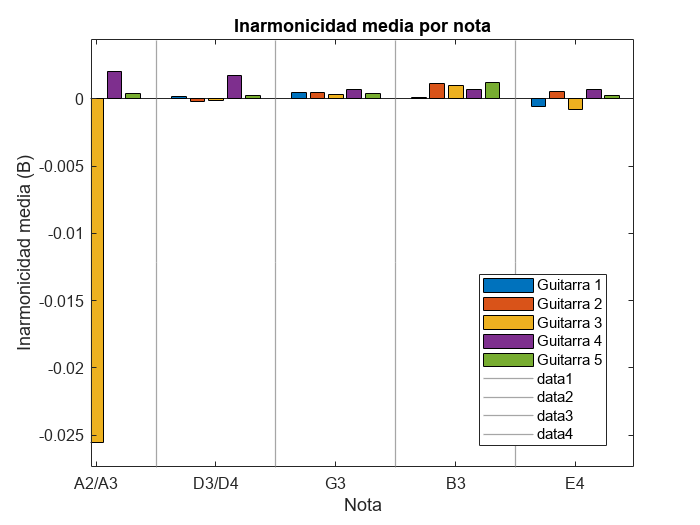

B_media = zeros(num_notas, num_guitarras);

for n = 1:num_notas
    for g = 1:num_guitarras
        filas = Resumen.Nota == n & Resumen.Guitarra == g;
        B_media(n, g) = mean(Resumen.Inarmonicidad(filas));
    end
end

figure;
b = bar(B_media(:, 1:5));
for k = 1:5
    b(k).DisplayName = sprintf('Guitarra %d', k);
end
set(gca, 'XTickLabel', etiquetas_415, 'XTick', 1:num_notas);
xlabel('Nota'); ylabel('Inarmonicidad media (B)');
title('Inarmonicidad media por nota');
legend(b, 'Location', 'best');
hold on;
for k = 1:num_notas-1
    x1 = xline(k+0.5, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.8); 
end
hold off;

% 
% figure;
% b = bar(B_media(:, 5));
% b.FaceColor = [0.4 0.8 0.4];  % verde
% set(gca, 'XTickLabel', etiquetas_440, 'XTick', 1:num_notas);
% xlabel('Nota'); ylabel('Inarmonicidad media (B)');
% title('Inarmonicidad media — Guitarra 5 (440 Hz)');
% legend('Guitarra 5', 'Location', 'best');


## FUNCIONES

function [f,SdBn] = espectro_nota(nota,fs)
% Calcula la d.e.p. de la nota, normalizado, en dB
    NFFT    = 2*fs;
    overlap = 16*NFFT/20;
    window  = hanning(NFFT);
    [S,f,t] = spectrogram(nota,window,overlap,NFFT,fs); % % Espectro en dB normalizado
    SdB     = 20*log10(mean(abs(S),2));
    SdBn    = SdB - max(SdB);
end

function [fp,picos,distancia] = picos_espectro(f,SdB,A,D,H)
% Búsqueda de picos. Devuelve las posiciones en frecuencia de los picos, la
% altura de los picos y la distancia entre picos. 
    [picos,loc] =  findpeaks(SdB,'MinPeakProminence',A,'MinPeakDistance',D,'MinPeakHeight',H);
    fp          =  f(loc);
    distancia   =  f(loc(2:end))-f(loc(1:end-1));
end

function [Slog,f,t] = espectrograma(x,Numpuntos,fs)
    overlap = Numpuntos/2;
    window  = hanning(Numpuntos);
    [S,f,t] = spectrogram(x,window,overlap,Numpuntos,fs);
    Slog    = 10*log10(abs(S.^2)/max(max((abs(S.^2)))));  % Espectrograma normalizado al máximo. 
end

function tabla2latex(fid, T, caption, label, fmtNum)
    if nargin < 5, fmtNum = '%.2f'; end

    nombres = T.Properties.VariableNames;
    ncol    = numel(nombres);

    tieneRowNames = ~isempty(T.Properties.RowNames);
    
    if tieneRowNames
        aln = 'l'; % La primera columna (Guitarra X) a la izquierda
    else
        aln = '';
    end
    
    %  'l' si es texto, 'r' si es número
    for j = 1:ncol
        if ~isnumeric(T.(nombres{j}))
            aln = [aln 'l']; 
        else
            aln = [aln 'c']; 
        end
    end

    % cambio nombres
    % Usamos regexprep con la opción 'ignorecase' para cambiar los nombres sin alterar los nombres de las notas
    caption = regexprep(caption, 'alejandro', 'Intérprete 1', 'ignorecase');
    caption = regexprep(caption, 'uxia', 'Intérprete 2', 'ignorecase');
    
    % Aseguramos que la primera letra del caption sea mayúscula
    if ~isempty(caption)
        caption(1) = upper(caption(1));
    end

    caption = regexprep(caption, '\s*__+\s*', ', ');

    % Forzamos que la sintaxis de f_0 cierre y abra adecuadamente en LaTeX matemático
    caption = strrep(caption, '($f_0', '($f_0$');
    caption = strrep(caption, 'hz)', 'Hz)');
    
    label = strrep(lower(label), 'alejandro', 'interprete1');
    label = strrep(lower(label), 'uxia', 'interprete2');

    % escribimos en archivo .tex
    fprintf(fid, '\\begin{table}[htbp]\n  \\centering\n \\small\n');
    fprintf(fid, '  \\caption{%s}\n  \\label{%s}\n', escapar(caption), label);
    fprintf(fid, '  \\begin{tabular}{%s}\n  \\toprule\n', aln);

    % Cabecera de columnas
    if tieneRowNames
        fprintf(fid, '   & %s \\\\\n  \\midrule\n', ...
                strjoin(cellfun(@escapar, nombres, 'UniformOutput', false), ' & '));
    else
        fprintf(fid, '  %s \\\\\n  \\midrule\n', ...
                strjoin(cellfun(@escapar, nombres, 'UniformOutput', false), ' & '));
    end

    % Filas de datos
    for i = 1:height(T)
        celdas = cell(1, ncol);
        for j = 1:ncol
            v = T.(nombres{j})(i);
            if isnumeric(v)

                col_name = nombres{j};

                % 1. COLUMNAS QUE DEBEN SER ENTEROS (%d)
                if any(strcmpi(col_name, {'Armónicos', 'Guitarra', 'Nota', 'Intérprete', 'Interprete'}))
                    celdas{j} = sprintf('%d', round(v));
                
                % 2. COLUMNAS DE INARMONICIDAD (6 decimales)
                % Usamos 'contains' para que afecte tanto a 'Inarmonicidad' como a 'Inarmonicidad media'
                elseif contains(col_name, 'Inarmonicidad', 'IgnoreCase', true)
                    celdas{j} = sprintf('%.6f', v);
                
                % 3. EL RESTO DE COLUMNAS NUMÉRICAS (Frecuencia, Distancia, Fundamental -> 1 decimal)
                else
                    celdas{j} = sprintf('%.1f', v);
                end
            else
                texto_celda = char(string(v));
                if strcmpi(texto_celda, 'alejandro')
                    texto_celda = 'Intérprete 1';
                elseif strcmpi(texto_celda, 'uxia')
                    texto_celda = 'Intérprete 2';
                end
                celdas{j} = escapar(texto_celda);
            end
        end
        
        % Si tiene RowNames los añade al principio de la fila, si no, escribe normal
        if tieneRowNames
            fprintf(fid, '  %s & %s \\\\\n', escapar(T.Properties.RowNames{i}), strjoin(celdas, ' & '));
        else
            fprintf(fid, '  %s \\\\\n', strjoin(celdas, ' & '));
        end
    end

    fprintf(fid, '  \\bottomrule\n  \\end{tabular}\n\\end{table}\n\n');
end

function s = escapar(s)
% Escapa los caracteres especiales de LaTeX mas habituales
    s = char(s);
    s = strrep(s, '\', '\textbackslash ');
    s = strrep(s, '&', '\&');
    s = strrep(s, '%', '\%');
    s = strrep(s, '#', '\#');
    s = strrep(s, '$', '');
    s = regexprep(s, '(?i)f_0\s*=\s*([\d\.]+)\s*hz', '\$f_0 = $1\$ Hz');
end